# Data Flow

close all
clear all
clc
load Telecom.mat

init();
%Frequency
f=145e6;%Hz
%Orbital Period
T=94*60;%seconds
t_array = 1:T;

## ADCS

adcs_bps=5;%B/s
T_s=5*60;%s - Oldest data stored (5 min)
adcs_data=data_input(adcs_bps,1,T);

## Thermal

temp_data=data_input(10,1,T);

## Payload

t_exp=20;%s - Duration of experiment
exp_t=1;%s - Start of experiment
payload_Bps=10e3;%B/s - Data produced by payload per second (10kB/s)
payload=data_input(payload_Bps,exp_t,(exp_t+t_exp));

## Transmission

add disturbance/noise due to interfearance 

bps = f;%*2/2;

Unrecognized function or variable 'f'.

Bps = bps/8;

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Access", "Difference", "StartTime", "Duration_sec_", "Var5", "Start", "x12_6_2024"];
opts.VariableTypes = ["double", "datetime", "double", "double", "string", "string", "datetime"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var5", "Start"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var5", "Start"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Difference", "InputFormat", "MM/dd/yyyy HH:mm", "DatetimeFormat", "preserveinput");
opts = setvaropts(opts, "x12_6_2024", "InputFormat", "MM/dd/yyyy", "DatetimeFormat", "preserveinput");

% Import the data
STKsimulation_RPI = readtable("/MATLAB Drive/Space Vehicle Design/STKsimulation_RPI.csv", opts);

% Clear temporary variables
clear opts

% Display results
STKsimulation_RPI
trans_data=zeros(size(t_array));

plot(trans_data)

## Storage

stored=adcs_data+temp_data+payload-trans_data;

stored =        10005       20010       30015       40020       50025       60030       70035       80040       90045      100050      110055      120060      130065      140070      150075      160080      170085      180090      190095      200100      210105      210110      210115      210120      210125      210130      210135      210140      210145      210150      210155      210160      210165      210170      210175      210180      210185      210190      210195      210200      210205      210210      210215      210220      210225      210230      210235      210240      210245      210250


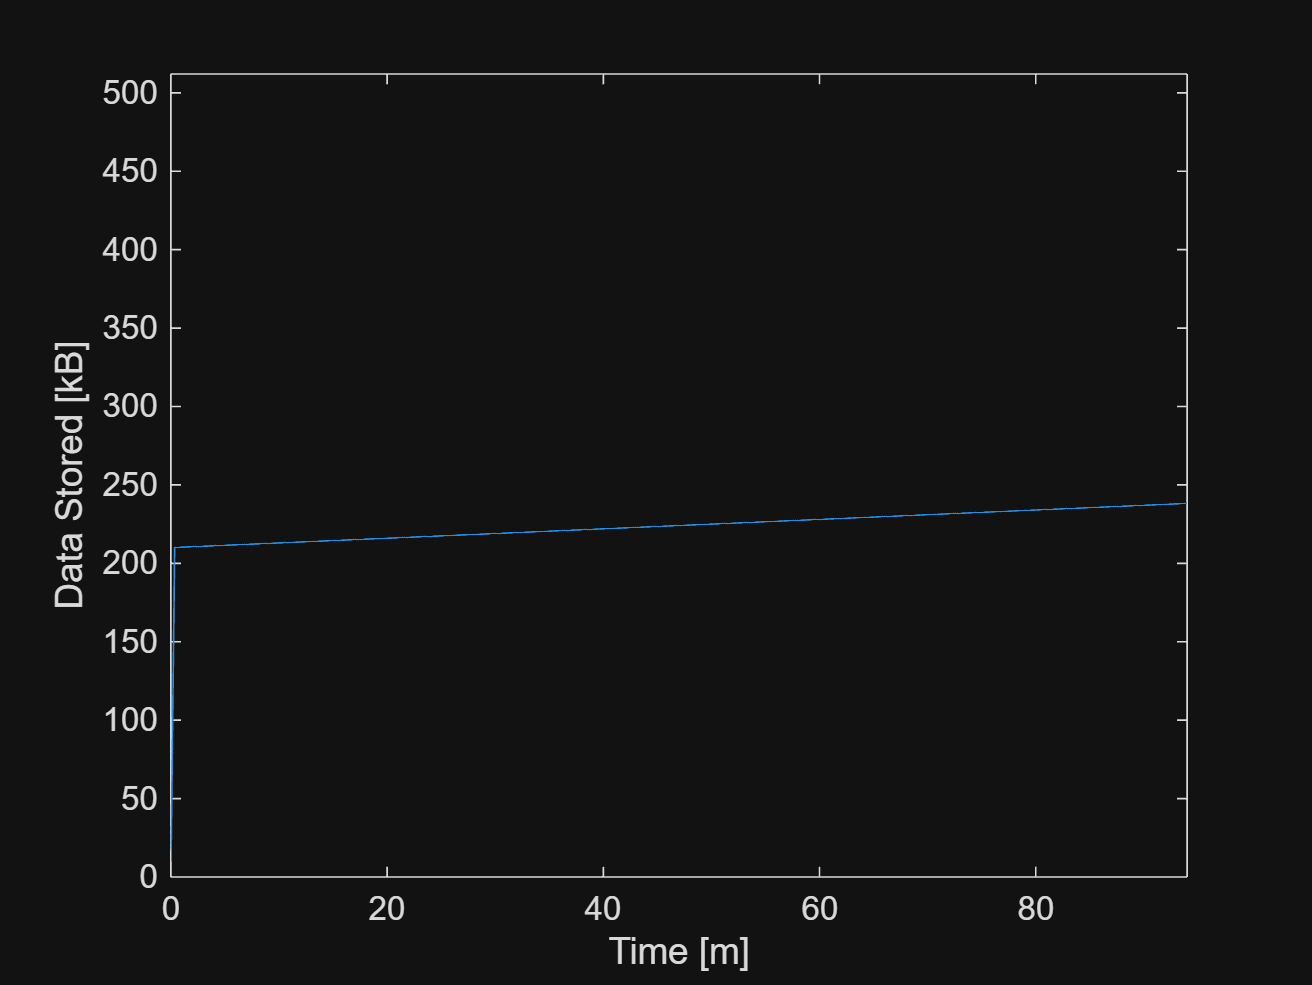

stored(stored<0) = 0;
plot(t_array/(60),stored/1e3)
ylim([0 512])
xlim([0 T/60])
ylabel("Data Stored [kB]")
xlabel("Time [m]")

function x = data_input(Bps,t_start,t_end)
    T=94*60;
    x=zeros([1 T]);
    x(t_start:(t_end+t_start-1))=(1:t_end)*Bps;
    x(t_end:end)=t_end*Bps;
end
function data_plot(x)
    plot(1:T,x/1e3)
    ylim([0 512])
    xlim([0 T])
    ylabel("Data Stored [kB]")
    xlabel("Time [s]")
end
function init()
    global T;
    T=94*60;%s - Orbital Period
end